# Monte Carlo analysis of a SISO feedback system

The goal of this example is to illustrate how a Monte Carlo approach can be used to study the performance of an uncertain SISO feedback system.

## Definition of uncertain parameters of the plant model

The plant includes three uncertain parameters: the gain gamma, the time constant tau of a real poles and the damping ratio xi of a pair of complex conjugate poles.

gamma = ureal('gamma',2,'Perc',30);  % uncertain gain

tau = ureal('tau',1,'Perc',30);      % uncertain time-constant

% parameters of second order mode
wn = 50; 
xi = ureal('xi',0.5,'Range',[0.1 0.8]);      % uncertain damping ratio

## Definition and inspection of plant model

The plant model is constructed as the cascade of the real and the complex mode:

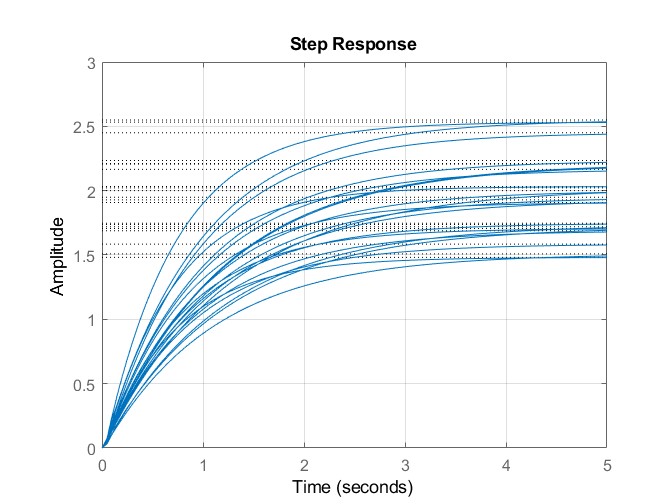

% uncertain plant
P = tf(gamma,[tau 1]) * tf(wn^2,[1 2*xi*wn wn^2]);

step(P,5), grid

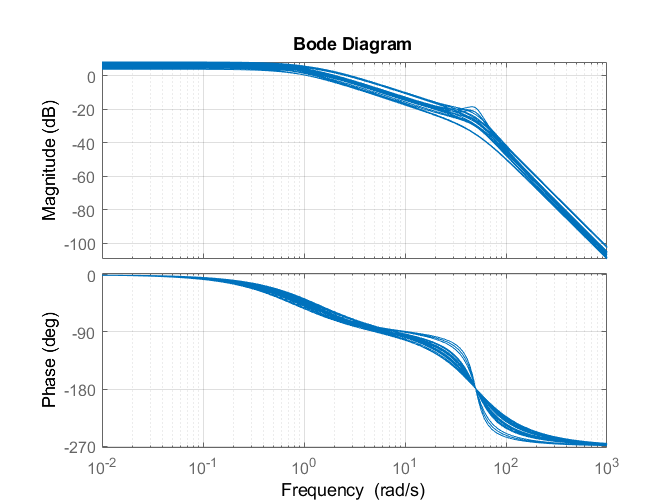


bode(P), grid

## Construction of uncertainty model for the plant

We now build a W-$\Delta$uncertain model for the plant, by resampling parametric uncertainty and overbounding relative errors with a weighitng functon Wt.

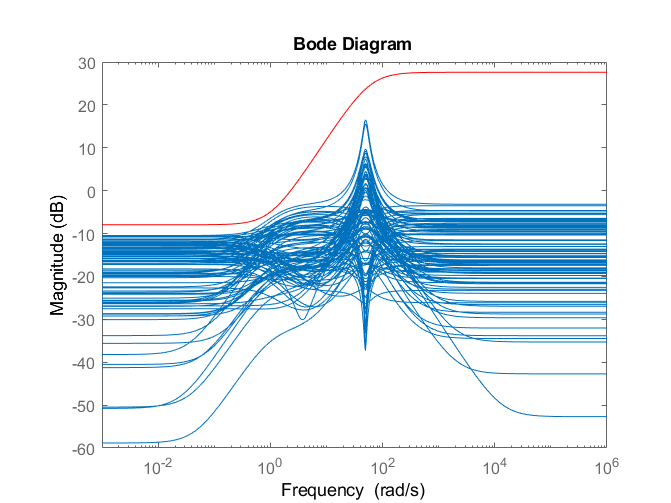

Parray = usample(P,100);

Pn = P.NominalValue;

Wt=tf(0.4*[1 1],[1/60 1]);

bodemag((Pn-Parray)/Pn,Wt,'r')

## Nominal controller, nominal performance and robust stability

We next pick a controller for the nominal plant and whether it satisfies classical criteria for nominal and robust stability.

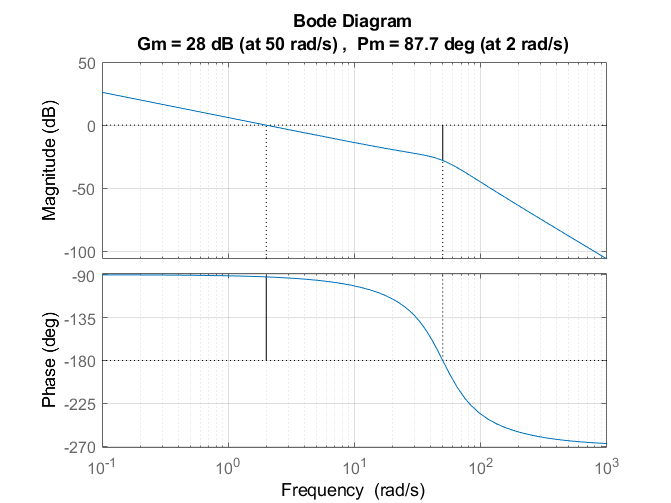

Cn=tf([1, 1],[1 0]);

margin(Pn*Cn), grid

5 states removed.


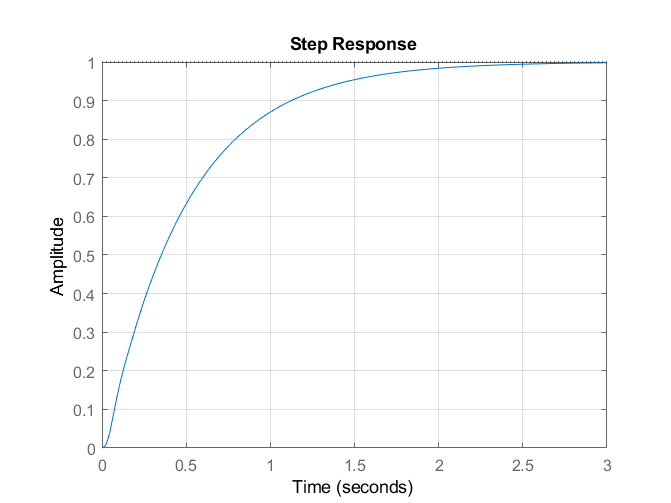


step(minreal(Pn*Cn/(1+Pn*Cn))), grid

5 states removed.


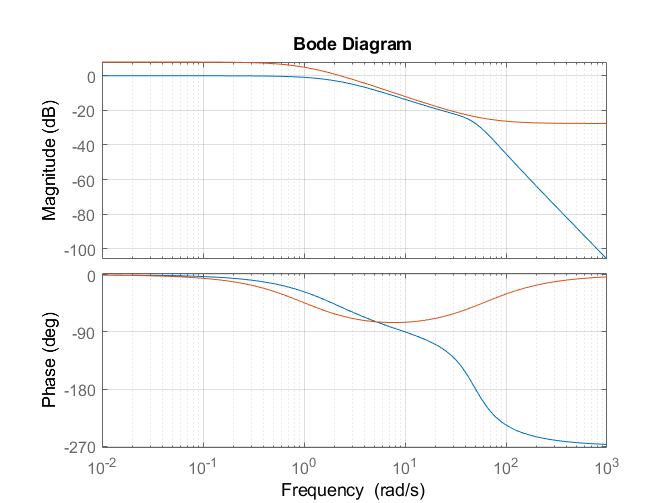


bode(minreal(Pn*Cn/(1+Pn*Cn)),1/Wt), grid

5 states removed.


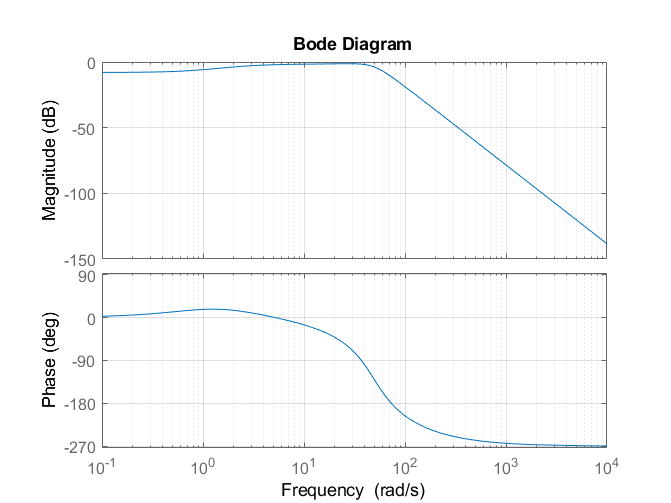


bode(minreal(Pn*Cn/(1+Pn*Cn)*Wt)), grid

## Monte Carlo study

Our conclusion is that the feedback system "passes" a classical stability analysis and is robustly stable (though barely) with respect to Wt.

However this does not provide us with detailed information about how stability and performance are affected by variations in the parameters and which combinations of the uncertain parameters are critical. To address this we can use a stochastic approach. Since the parameters are defined in a range, we use a uniform probability density function to resample.

% Number of sammes in the MC study
N=500;

gamma_mc=zeros(N);
tau_mc=zeros(N);
xi_mc=zeros(N);

for n=1:N
    
    % Resampling of uncertain parameters
    gamma_mc(n)= 0.7*2 + (1.3-0.7)*2*rand(1,1);
    tau_mc(n)= 0.7*1 + (1.3-0.7)*1*rand(1,1);
    xi_mc(n)= 0.1 + (0.8-0.1)*rand(1,1);
    
    % Construction of resampled uncertain plant
    P_mc(n) = tf(gamma_mc(n),[tau_mc(n) 1]) * tf(wn^2,[1 2*xi_mc(n)*wn wn^2]);
    
    % Computation of gain and phase margins
    [Gm(n),Pm(n)] = margin(P_mc(n)*Cn);
    
    % Computation of steo response 
    t=(0:.01:10);
    
    y=step(minreal(P_mc(n)*Cn/(1+P_mc(n)*Cn)),t);
    
    % Computation of step response characteristics
    S = stepinfo(y,t,1);
    
    Sett(n)=S.SettlingTime;
    Over(n)=S.Overshoot;
    
end

## Analysis of the results

We can now plot the results to study the features of our system. The results are visualised as histograms of the relevant performance metrics. 

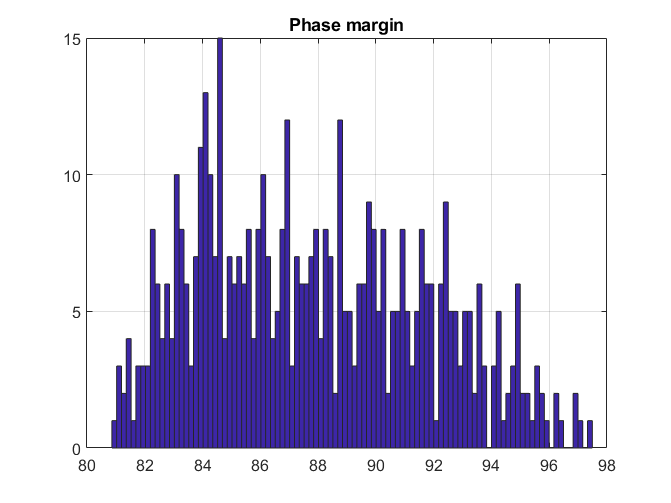

% Plot the histogram of phase margin

hist(Pm,100), grid, title('Phase margin')

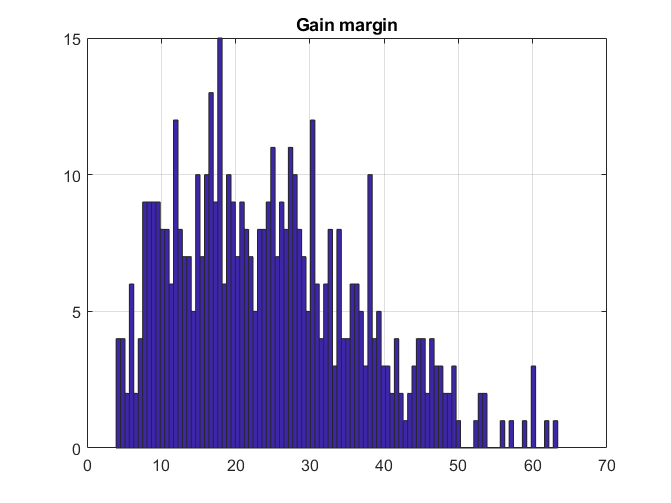


% Plot the histogram of gain margin

hist(Gm,100), grid, title('Gain margin')

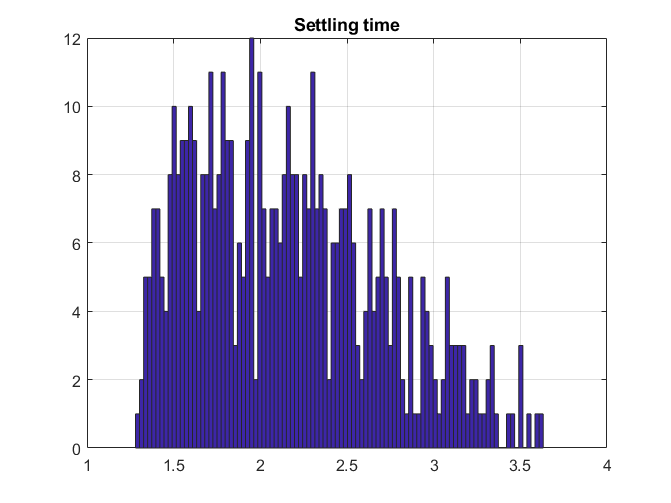


% Plot the histogram of settling time

hist(Sett,100), grid, title('Settling time')

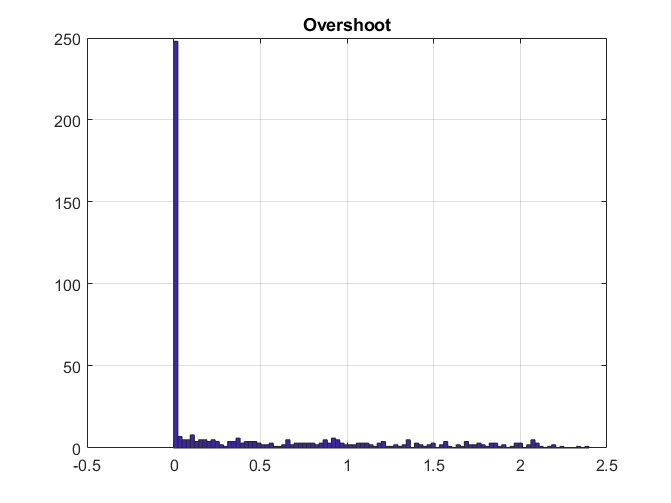


% Plot the histogram of overshoot

hist(Over,100), grid, title('Overshoot')

## Studying worst cases

The analysis shows that for some combinations of uncertainty the settling time may become very long. We can use the results to find in which cases this happens and analyse in detail.

% find MC case corresponding to worst settling time

max_Sett=max(Sett)

max_Sett =    3.631968273516563



worst=find(Sett==max_Sett)

worst =    336


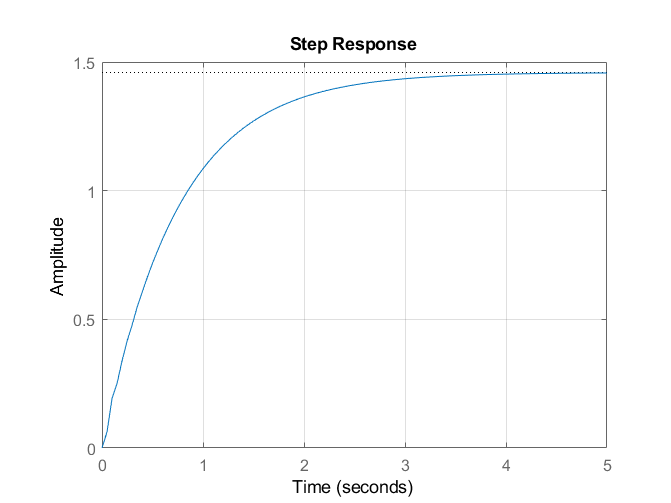


% Find worst case uncertainty

gamma_w=gamma_mc(worst);
tau_w=tau_mc(worst);
xi_w=xi_mc(worst);

% Construct worst case uncertain plant 

P_w = tf(gamma_w,[tau_w 1]) * tf(wn^2,[1 2*xi_w*wn wn^2]);

step(P_w,5), grid

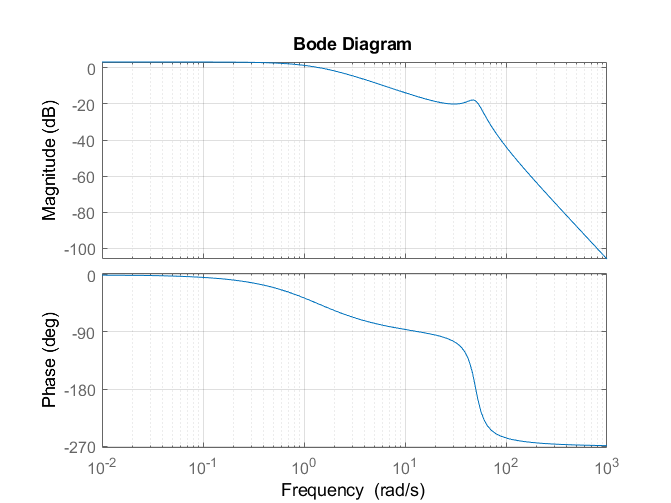


bode(P_w), grid

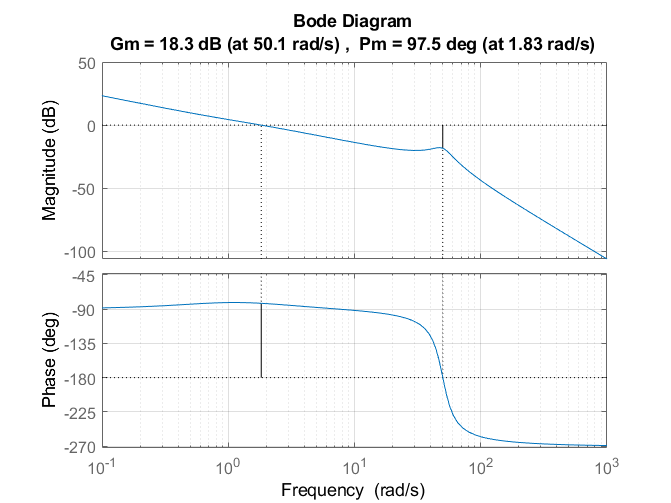


margin(P_w*Cn), grid